## 1) Date le matrici che seguono creare la matrice C=AxB

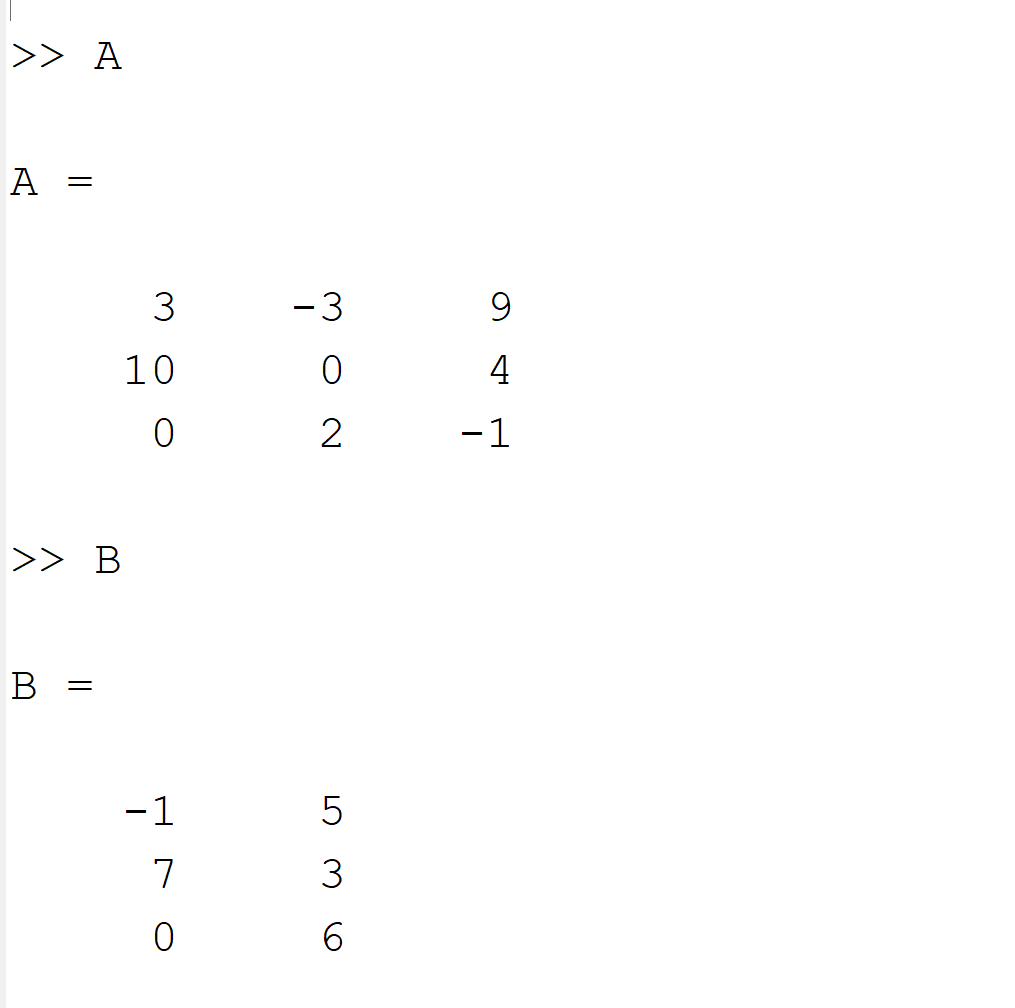

A=[3 -3 9; 10 0 4; 0 2 -1];
B=[-1 5; 7 3; 0 6];
C=A*B;
disp(C)

   -24    60
   -10    74
    14     0



## 2) Creare una matrice diagonale che contiene sulla diagonale principale gli elementi 1,3,5,...,17

A=diag(1:2:17);
disp(A)

     1     0     0     0     0     0     0     0     0
     0     3     0     0     0     0     0     0     0
     0     0     5     0     0     0     0     0     0
     0     0     0     7     0     0     0     0     0
     0     0     0     0     9     0     0     0     0
     0     0     0     0     0    11     0     0     0
     0     0     0     0     0     0    13     0     0
     0     0     0     0     0     0     0    15     0
     0     0     0     0     0     0     0     0    17



## 3) Caricare in memoria il file car.mat di FSDA toolbox tramite l'istruzione load('car.mat'). Viene caricata in memora una table denominata car di dimensione 39x7. La table car è la tabella di contingenza (in formato table) riferita a 7 caratteristiche percepite dei 39 modelli di auto. Ad esempio l'elemento car(4,1) significa che in 14 casi gli intervistati hanno dichiarato che il modello di auto BWM si caratterizza per "fuel economy" ossia per consumare poco. Visualizzare nella command window la descrizione della table. 

## Calcolare la table dei profili riga e dei profili colonna. 

## Osservazione: nella tabella dei profili riga ogni frequenza viene divisa per il totale di riga. Nella tabella dei profili colonna ogni frequenza è divisa per il totale di colonna. Chiamare queste due tabelle ProfileRows e ProfileCols. Mostrare nella command le prime 10 righe della table ProfileRows utilizzando il formato con due cifre decimali.

## Anteprima output delle prime 10 righe della table ProfileRows

## 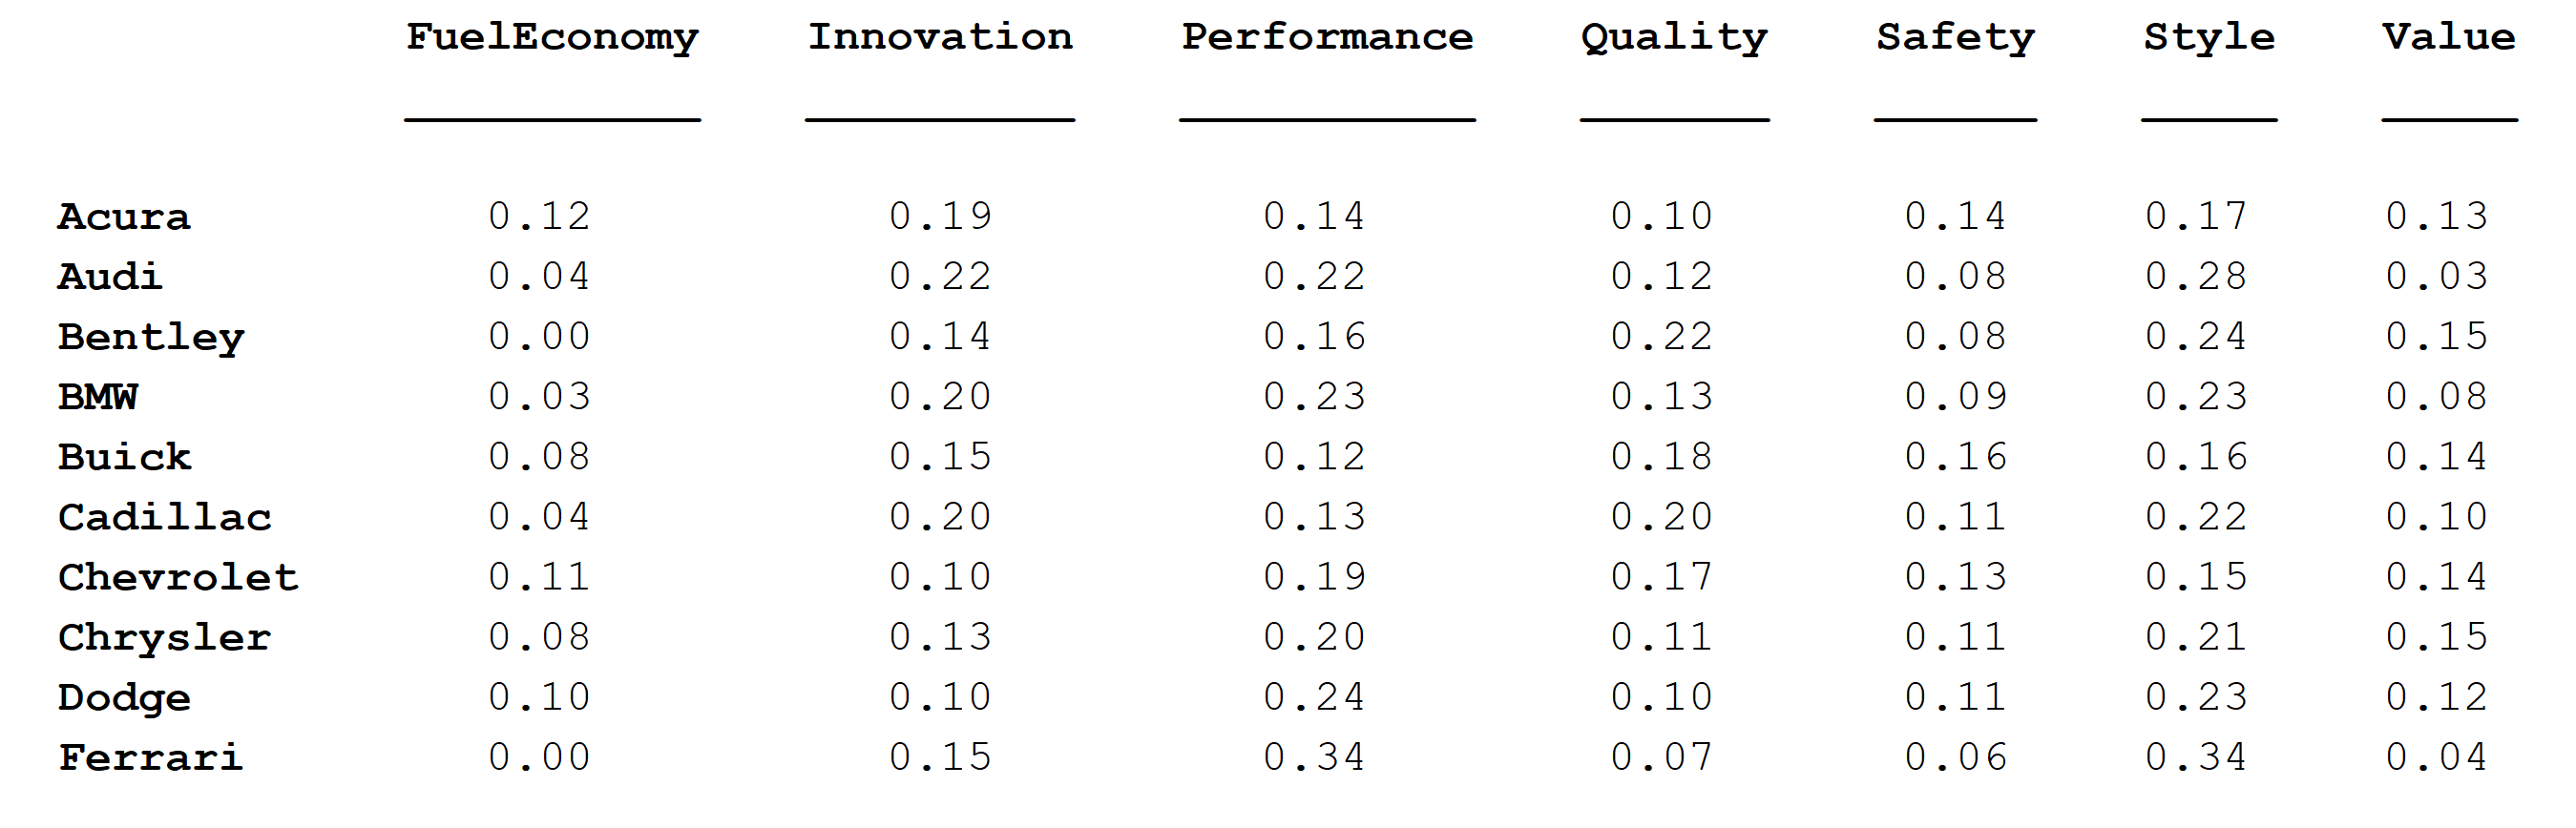

## Interpretare  i numeri 0 e 0.34 nel profilo riga della Ferrari.

## Mostrare nella command le ultime 10 righe della table dei profili colonna utilizzando un formato con due cifre decimali.

## Anteprima output delle ultime 10 righe della table ProfileCols

## 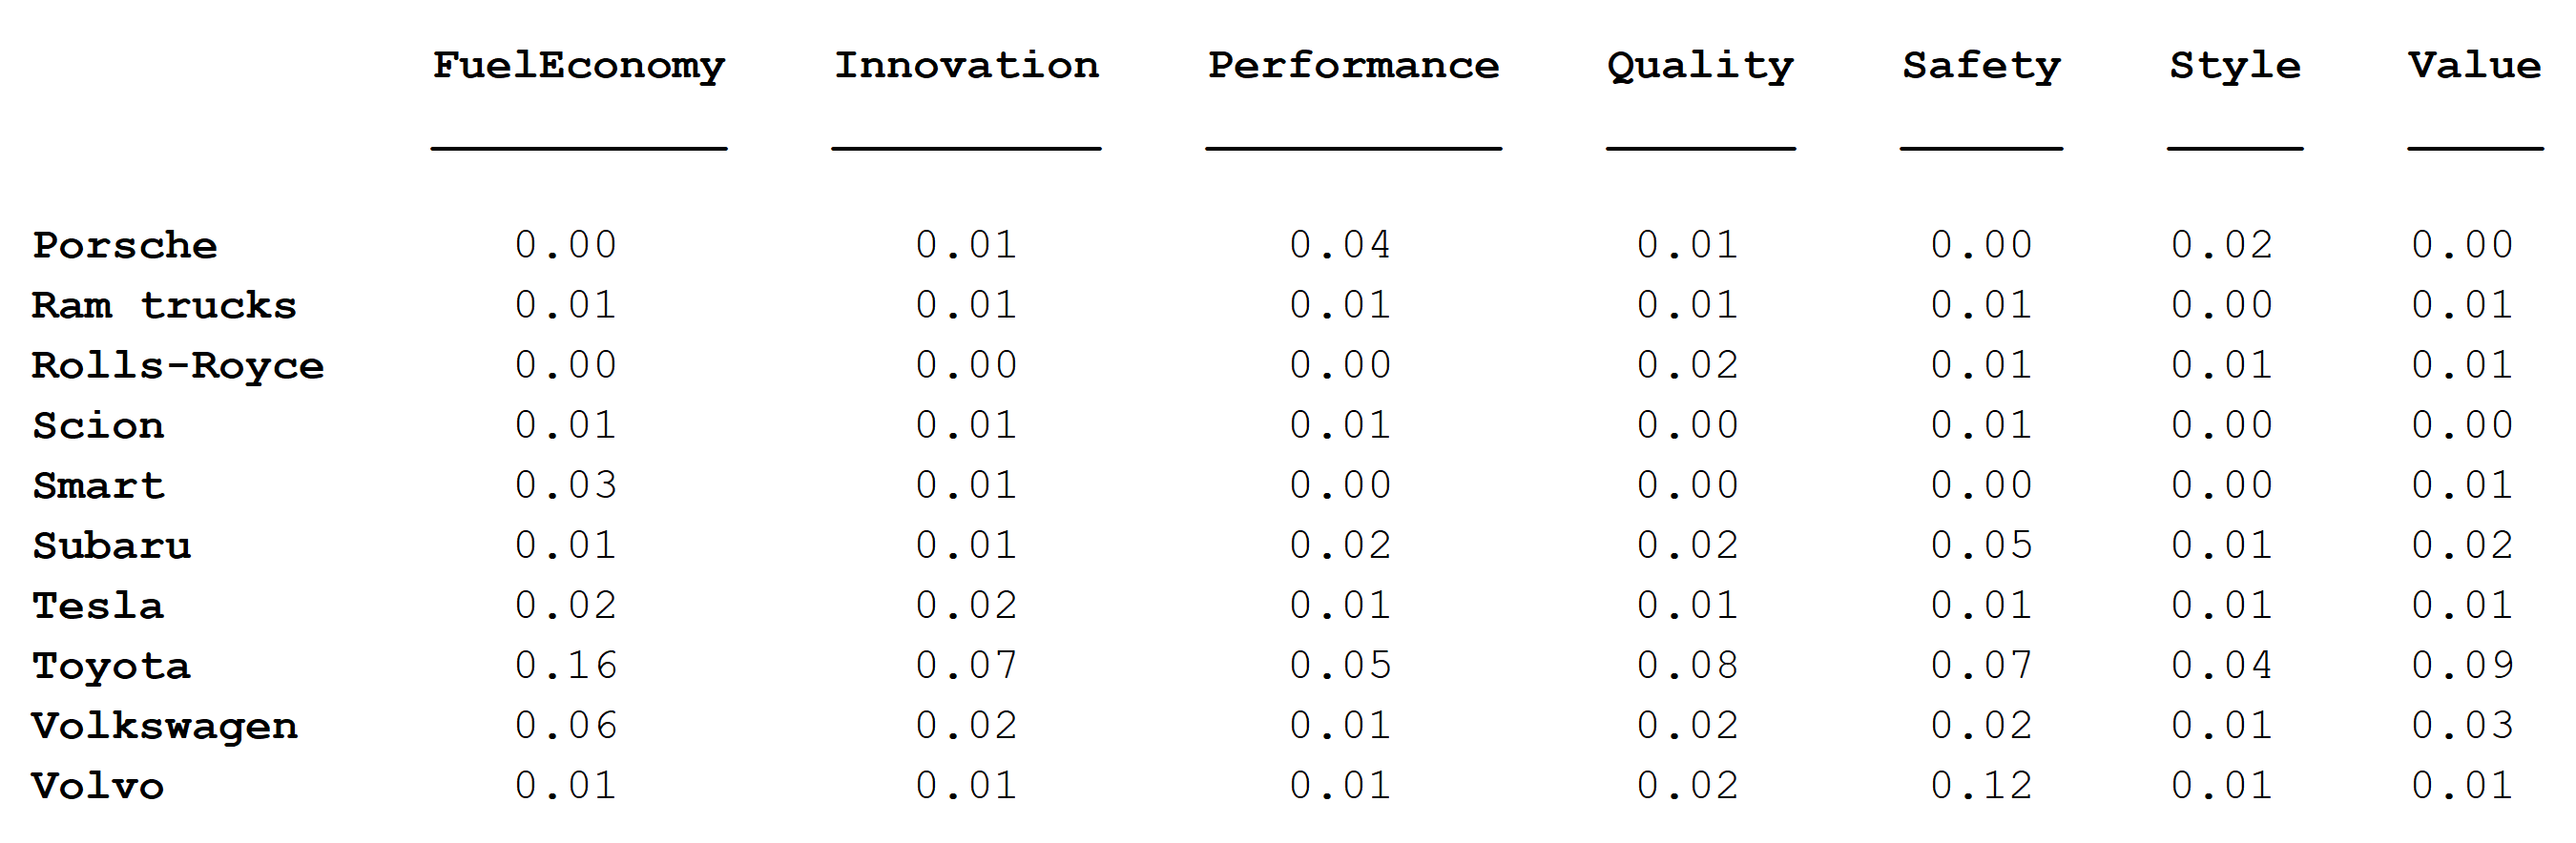

## Interpretare il numero 0.12 per l'attributo Safety associato alla Volvo.

## Ripristinare il formato di visualizzazione di default dei numeri (ossia il formato short).

load("car.mat")
% Visualizzo la descrizione della tabella nella command
disp(car.Properties.Description)

The car dataset is a contingency table referred to number of adults out of 1578 stating that a particular make of vehicle had a specific quality. In all there are 11713 counts. These data are taken from the 2014 Auto Brand Perception survey by Consumer Reports


% Inizializzo le tables ProfileRows e ProfileCols
ProfileRows=car;
ProfileCols=car;
% carSoloNumeri = matrice che contiene solo i numeri e non le intestazioni di
% riga e colonna
carSoloNumeri=car{:,:};
% Per calcolare i profili riga divido le frequenze di ogni riga per il totale di riga
ProfileRows{:,:}=carSoloNumeri./sum(carSoloNumeri,2);
% Per calcolare i profili colonna divido le frequenze di ogni colonna per
% il totale di colonna
ProfileCols{:,:}=carSoloNumeri./sum(carSoloNumeri,1);

% formato con due cifre decimali
format bank
% mostro le prime 10 righe della table dei profili riga
disp(ProfileRows(1:10,:))

                 FuelEconomy    Innovation    Performance    Quality    Safety    Style    Value
                 ___________    __________    ___________    _______    ______    _____    _____

    Acura           0.12           0.19          0.14         0.10       0.14     0.17     0.13 
    Audi            0.04           0.22          0.22         0.12       0.08     0.28     0.03 
    Bentley         0.00           0.14          0.16         0.22       0.08     0.24     0.15 
    BMW             0.03           0.20          0.23         0.13       0.09     0.23     0.08 
    Buick           0.08           0.15          0.12         0.18       0.16     0.16     0.1

%  Il numero 0 per FuelEconomy di Ferrari significa che nessuno degli
%  intervistati ha dichiarato che la Ferrari si contraddistigue per
%  consumare poco.  Posto pari a 100 il numero delle caratteristiche
%  riferite a Ferrari, nel 34 per cento dei casi  gli intervistati
%  associano alla Ferrari la caratteristica della Performance. Le
%  caratteristiche Performance e Style sono quelle maggiormente percepite
%  di questo modello di auto.


% mostro le ultime 10 righe della table dei profili colonna
disp(ProfileCols(end-9:end,:))

                   FuelEconomy    Innovation    Performance    Quality    Safety    Style    Value
                   ___________    __________    ___________    _______    ______    _____    _____

    Porsche           0.00           0.01          0.04         0.01       0.00     0.02     0.00 
    Ram trucks        0.01           0.01          0.01         0.01       0.01     0.00     0.01 
    Rolls-Royce       0.00           0.00          0.00         0.02       0.01     0.01     0.01 
    Scion             0.01           0.01          0.01         0.00       0.01     0.00     0.00 
    Smart             0.03           0.01          0.00         0.00       0.00   

%  Il numero 0.12 di volvo in corrispondenza dell'attributo Safety
%  significa che fatto 100 il numero di volte in cui è stato menzionato
%  l'attributo safety, nel 12 per cento dei casi questo attributo è stato
%  associato a Volvo. 

% ripristino il formato di visualizzazione di default
format default

## 4) Risolvere il seguente sistema di equazioni lineari di 4 equazioni e 4 incognite x1, x2, x3 e x4. Trovare il vettore x=(x1;x2;x3;x4)

(per un esercizio simile si veda esercizio 2.13 di p. 73 del libro di testo).

3x1+4x2+7x3+8x4=2

x2+x4=10

x1-x3+3x4=2

x1+3x2-2x4=8

Verificare la soluzione trovata.

% A = Matrice dei coefficienti del sistema lineare
A=[3 4 7 8; 0 1 0 1; 1 0 -1 3; 1 3 0 -2];
% b = vettore colonna che contiene i termini noti
b=[2; 10; 2; 8];
% Il sistema in termini matriciali è A x= b
x=A\b; % oppure potevo usare x=A^-1*b oppuure x=inv(A)*b
disp(x)

   -8.9333
    7.3867
   -3.0933
    2.6133



% Verifico la soluzione trovata
assert(max(abs(A*x-b))<1e-13)


## 5) Creare la matrice circolante riportata di seguito

  1     2     3     4     5     6     7

  7     1     2     3     4     5     6

  6     7     1     2     3     4     5

  5     6     7     1     2     3     4

  4     5     6     7     1     2     3

  3     4     5     6     7     1     2

  2     3     4     5     6     7     1

Suggerimento: utilizzare la funzione gallery oppure un ciclo for. 

Nel caso del ciclo for utilizzare la funzione circshift

Verificare che le due implementazioni coincidano

% Implementazione tramite la funzione gallery
A=gallery('circul',7);
disp('Matrice circolante di ordine 7 tramite la funzione gallery')

Matrice circolante di ordine 7 tramite la funzione gallery


disp(A)

     1     2     3     4     5     6     7
     7     1     2     3     4     5     6
     6     7     1     2     3     4     5
     5     6     7     1     2     3     4
     4     5     6     7     1     2     3
     3     4     5     6     7     1     2
     2     3     4     5     6     7     1



% Implementazione tramite ciclo for
k=7;
A1=zeros(k);
A1(1,:)=1:k;
for i=2:k
    % la riga i-esima è uguale alla riga i-1 shiftata di 1
    A1(i,:)=circshift(A1(i-1,:),1);
end

% Controllo uguaglianza delle due implementazioni
assert(isequal(A,A1),"Le due implementazioni differiscono")

## 6)  Data la matrice al punto 5), calcolare la somma dei quadrati utilizzando la funzione sum oppure la funzione trace. Verificare tramite assert l'uguaglianza dei due risultati

A=gallery('circul',7);
sum2A=sum(A.^2,"all");
sum2Achk=trace(A'*A);
disp(['Somma dei quadrati matrice circolante di ordine 7=' num2str(sum2A)])

Somma dei quadrati matrice circolante di ordine 7=980


assert(isequal(sum2A,sum2Achk),"Implementazioni non coincidono")

## 7) Partendo dalla matrice magica di ordine 6, 

### a) estrarre la matrice triangolare superiore

### b) estrarre in un vettore colonna gli elementi che si trovano sulla diagonale superiore a quella principale

### c) estrarre in un vettore riga gli elementi che fanno parte della matrice triangolare superiore 

X=magic(6);
disp('Matrice magica di ordine 6')

Matrice magica di ordine 6


disp(X)

    35     1     6    26    19    24
     3    32     7    21    23    25
    31     9     2    22    27    20
     8    28    33    17    10    15
    30     5    34    12    14    16
     4    36    29    13    18    11




% Estrazione della matrice triangolare superiore
Y=triu(X);
disp('Matrice triangolare superiore della matrice magica di ordine 6')

Matrice triangolare superiore della matrice magica di ordine 6


disp(Y)

    35     1     6    26    19    24
     0    32     7    21    23    25
     0     0     2    22    27    20
     0     0     0    17    10    15
     0     0     0     0    14    16
     0     0     0     0     0    11



% Estrazione degli elementi sopra la diagonale principale della matrice
% magica di ordine 6 in un vettore colonna 
v=diag(X,1);

disp('Estrazioni elementi sopra la diagonale principale')

Estrazioni elementi sopra la diagonale principale


disp(v)

     1
     7
    22
    10
    16




% Estrazione degli elementi della parte triangolare superiore in un vettore
% riga
% Implementazione tramite funzione specifica triu2vec
Y1=triu2vec(X)'

Y1 =     35     1    32     6     7     2    26    21    22    17    19    23    27    10    14    24    25    20    15    16    11



% Implementazione manuale partendo dalla matrice triangolare superiore.
% Creo una copia di Y e la assegno alla variabile Y2
Y2=Y;
% L'istruzione di seguito significa: tutti gli elementi di Y2 che sono
% uguali a zero vengono eliminati. 
% Osservazione: l'istruzione di seguito presuppone che tutti elementi sopra
% la diagonale principale siano diversi da zero (nella matrice magica
% questa assunzione è sempre vera).
Y2(Y2==0)=[]

Y2 =     35     1    32     6     7     2    26    21    22    17    19    23    27    10    14    24    25    20    15    16    11


## 8) Creare un array di stringhe con i seguenti elementi A6, A9, A12, ..., A24

as="A"+(6:3:24);
% Nel testo dell'esercizio non è specificato se il vettore deve essere riga
% o colonna. 
disp(as)

    "A6"    "A9"    "A12"    "A15"    "A18"    "A21"    "A24"



## 9) Generare una matrice di dimensione 3x4 denominata X da una N(5,1) utilizzando il seed 123. Calcolare la media di ogni colonna in un vettore denominato medieCol e la media di ogni riga in un vettore denominato medieRig

rng(123)
X=randn(3,4)+5;
disp('Medie colonna matrice X')

Medie colonna matrice X


medieCol=mean(X,1);
disp(medieCol)

    4.7081    5.1820    5.6409    4.9048




disp('Medie riga matrice X')

Medie riga matrice X


medieRig=mean(X,2);
disp(medieRig)

    5.5012
    5.0324
    4.7932



## 10) Calcolare la media potenziata di ordine s dei seguenti numeri 21 23 22 28 22 18 24 30 21. Aggiungere una slider bar per la variabile s (con valore minimo -3, valore massimo 3,  passo 1 e valore di default 2. Inserire come label del controllo "Media potenziata di ordine s".

x=[21 23 22 28 22 18 24 30 21]

x =     21    23    22    28    22    18    24    30    21


s=2;
% calcolo media potenziata di ordine s

n=length(x);

n = 9

% L'istruzione abs(s)>1e-7  è il modo computazionale di scrivere se è
% diverso da zero. Letteralemente l'istruzione if abs(s)>1e-7 significa "se
% la variabile s in valore assoluto è maggiore di 10^-7=0.0000001"

if abs(s)>1e-7   
    xs=x.^s;
    Ms=(sum(xs)/n)^(1/s);
else
    % se s=0 allora la media potenziata di ordine s non è altro che la
    % media geometrica
    xs=log(x);
    Ms=exp(mean(xs));
end
% Osservazione: si noti che la media potenziata di ordine s è funzione
% crescente di 2. In altri termini M_3>M_2>M_1=M>Mg>M_-1>M_-2M_-3
disp(['Calcolo media potenziata di ordine s=' num2str(s) '=' num2str(Ms)])

Calcolo media potenziata di ordine s=2=23.4829


## 11) Creare la table riportata di seguito utilizzando come nomi delle righe quelli riportati nella variabile biscotti. Denominare la table Xt. Calcolare media e mediana delle due variabili della table

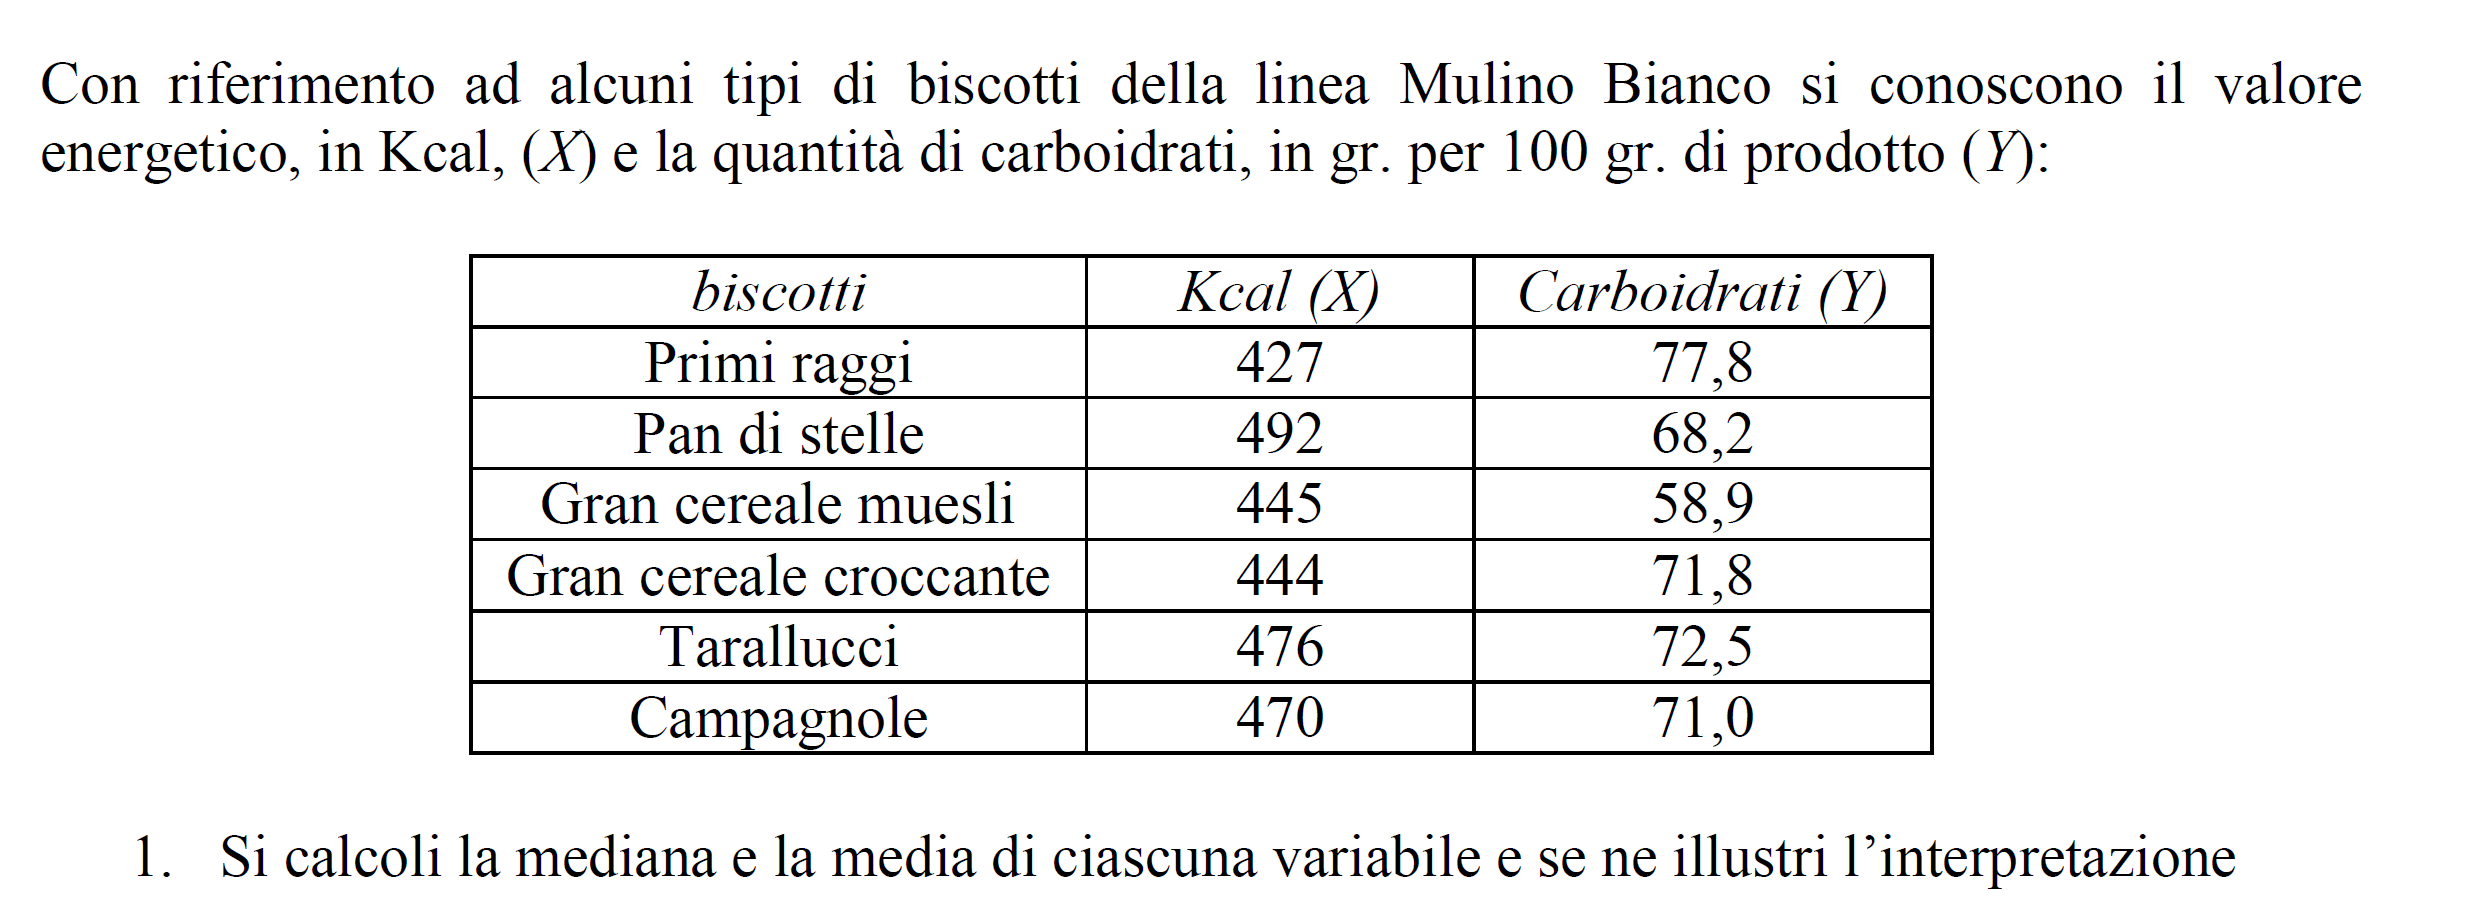

Kcal=[427; 492; 445; 444; 476; 470];
Carboidrati=[77.8; 68.2; 58.9; 71.8; 72.5; 71.0];
biscotti={'Primi raggi' 'Pan di stelle' 'Gran cereale muesli' 'Gran cereale croccante' 'Tarallucci' 'Campagnole'};
Xt=table(Kcal,Carboidrati,'RowNames',biscotti)

Xt = 6×2 table
                              Kcal    Carboidrati
                              ____    ___________

    Primi raggi               427        77.8    
    Pan di stelle             492        68.2    
    Gran cereale muesli       445        58.9    
    Gran cereale croccante    444        71.8    
    Tarallucci                476        72.5    
    Campagnole                470          71    


% Array X solo valori numerici
X=[Kcal,Carboidrati];
nomivar=Xt.Properties.VariableNames;
disp('Medie aritmetiche')

Medie aritmetiche


disp(nomivar)

    {'Kcal'}    {'Carboidrati'}



mean(X)

ans =   459.0000   70.0333


disp('Mediane')

Mediane


disp(nomivar)

    {'Kcal'}    {'Carboidrati'}



median(X)

ans =   457.5000   71.4000


In alternativa si poteva utilizzare l'istruzione

meanmed=grpstats(Xt,[],{'mean' 'median'});
% Il secondo argomento di grpstats è vuoto dato che in questo caso non c'è
% una variabile di raggruppamento
disp(meanmed)

           GroupCount    mean_Kcal    median_Kcal    mean_Carboidrati    median_Carboidrati
           __________    _________    ___________    ________________    __________________

    All        6            459          457.5            70.033                71.4       



## 12) Media e sigma in distribuzioni di frequenze

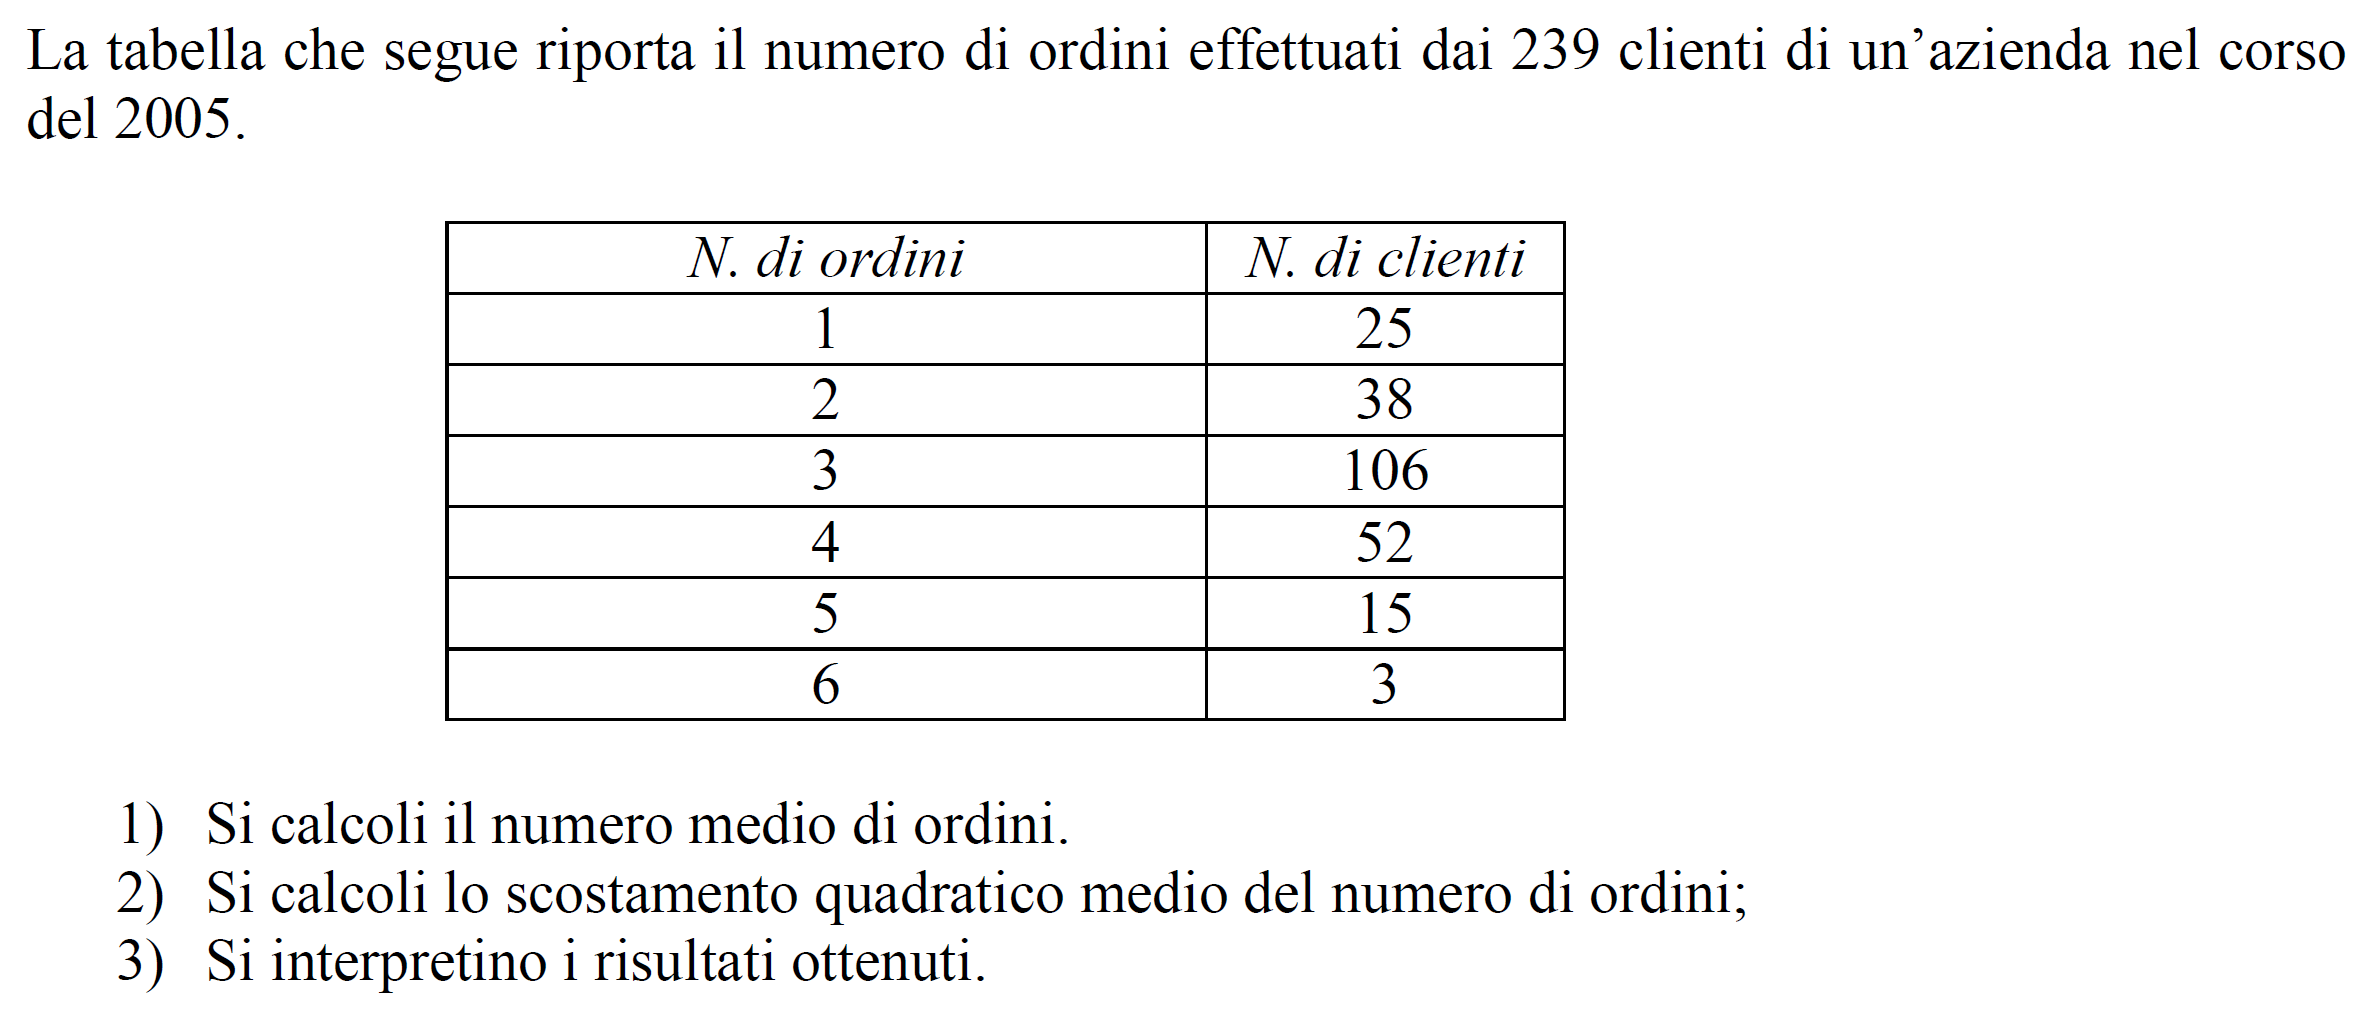

xi=(1:6)';
ni=[25; 38; 106; 52; 15; 3];
n=sum(ni);
% M=media ponderata (implementazione manuale)
M=sum(xi.*ni)/n;
% s= scostamento quadratico medio ponderato (implementazoine manuale)
s=sqrt(sum((xi-M).^2.*ni)/n);

% s1 = sigma ponderato (tramite funzione std)
s1=std(xi,ni);
% Controllo l'uguaglianza delle due implementazioni
assert(abs(s-s1)<1e-12,"Le due implentazioni della media differiscono")



## 13) Differenza media assoluta 

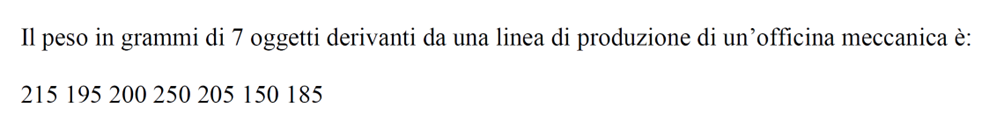

Si calcoli la differenza media assoluta

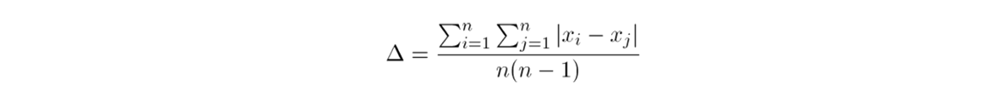

Denominata la differenza media assoluta Delta 

Implementare per il calcolo di Delta anche la formula che segue

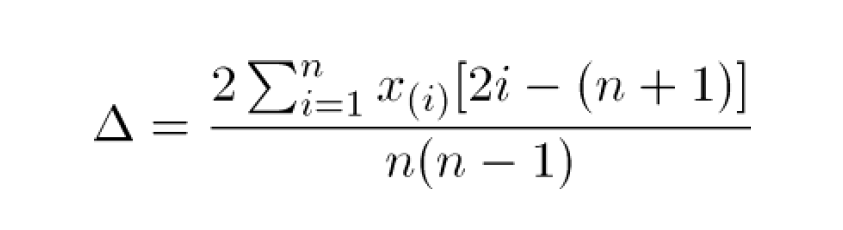

x=[215; 195; 200; 250; 205; 150; 185];

n=length(x);
% D= Matrice delle distanze
D=abs(x-x');
Delta=sum(D,"all")/(n*(n-1));
disp(['Differenza media assoluta=' num2str(Delta)])

Differenza media assoluta=35.2381


n=length(x);
seq=(1:n);
DeltaCHK=2*(2*seq-(n+1))*sort(x)/(n*(n-1));
disp(['Differenza media assoluta seconda implementazione=' num2str(DeltaCHK)])

Differenza media assoluta seconda implementazione=35.2381


## 14) calcolo CV

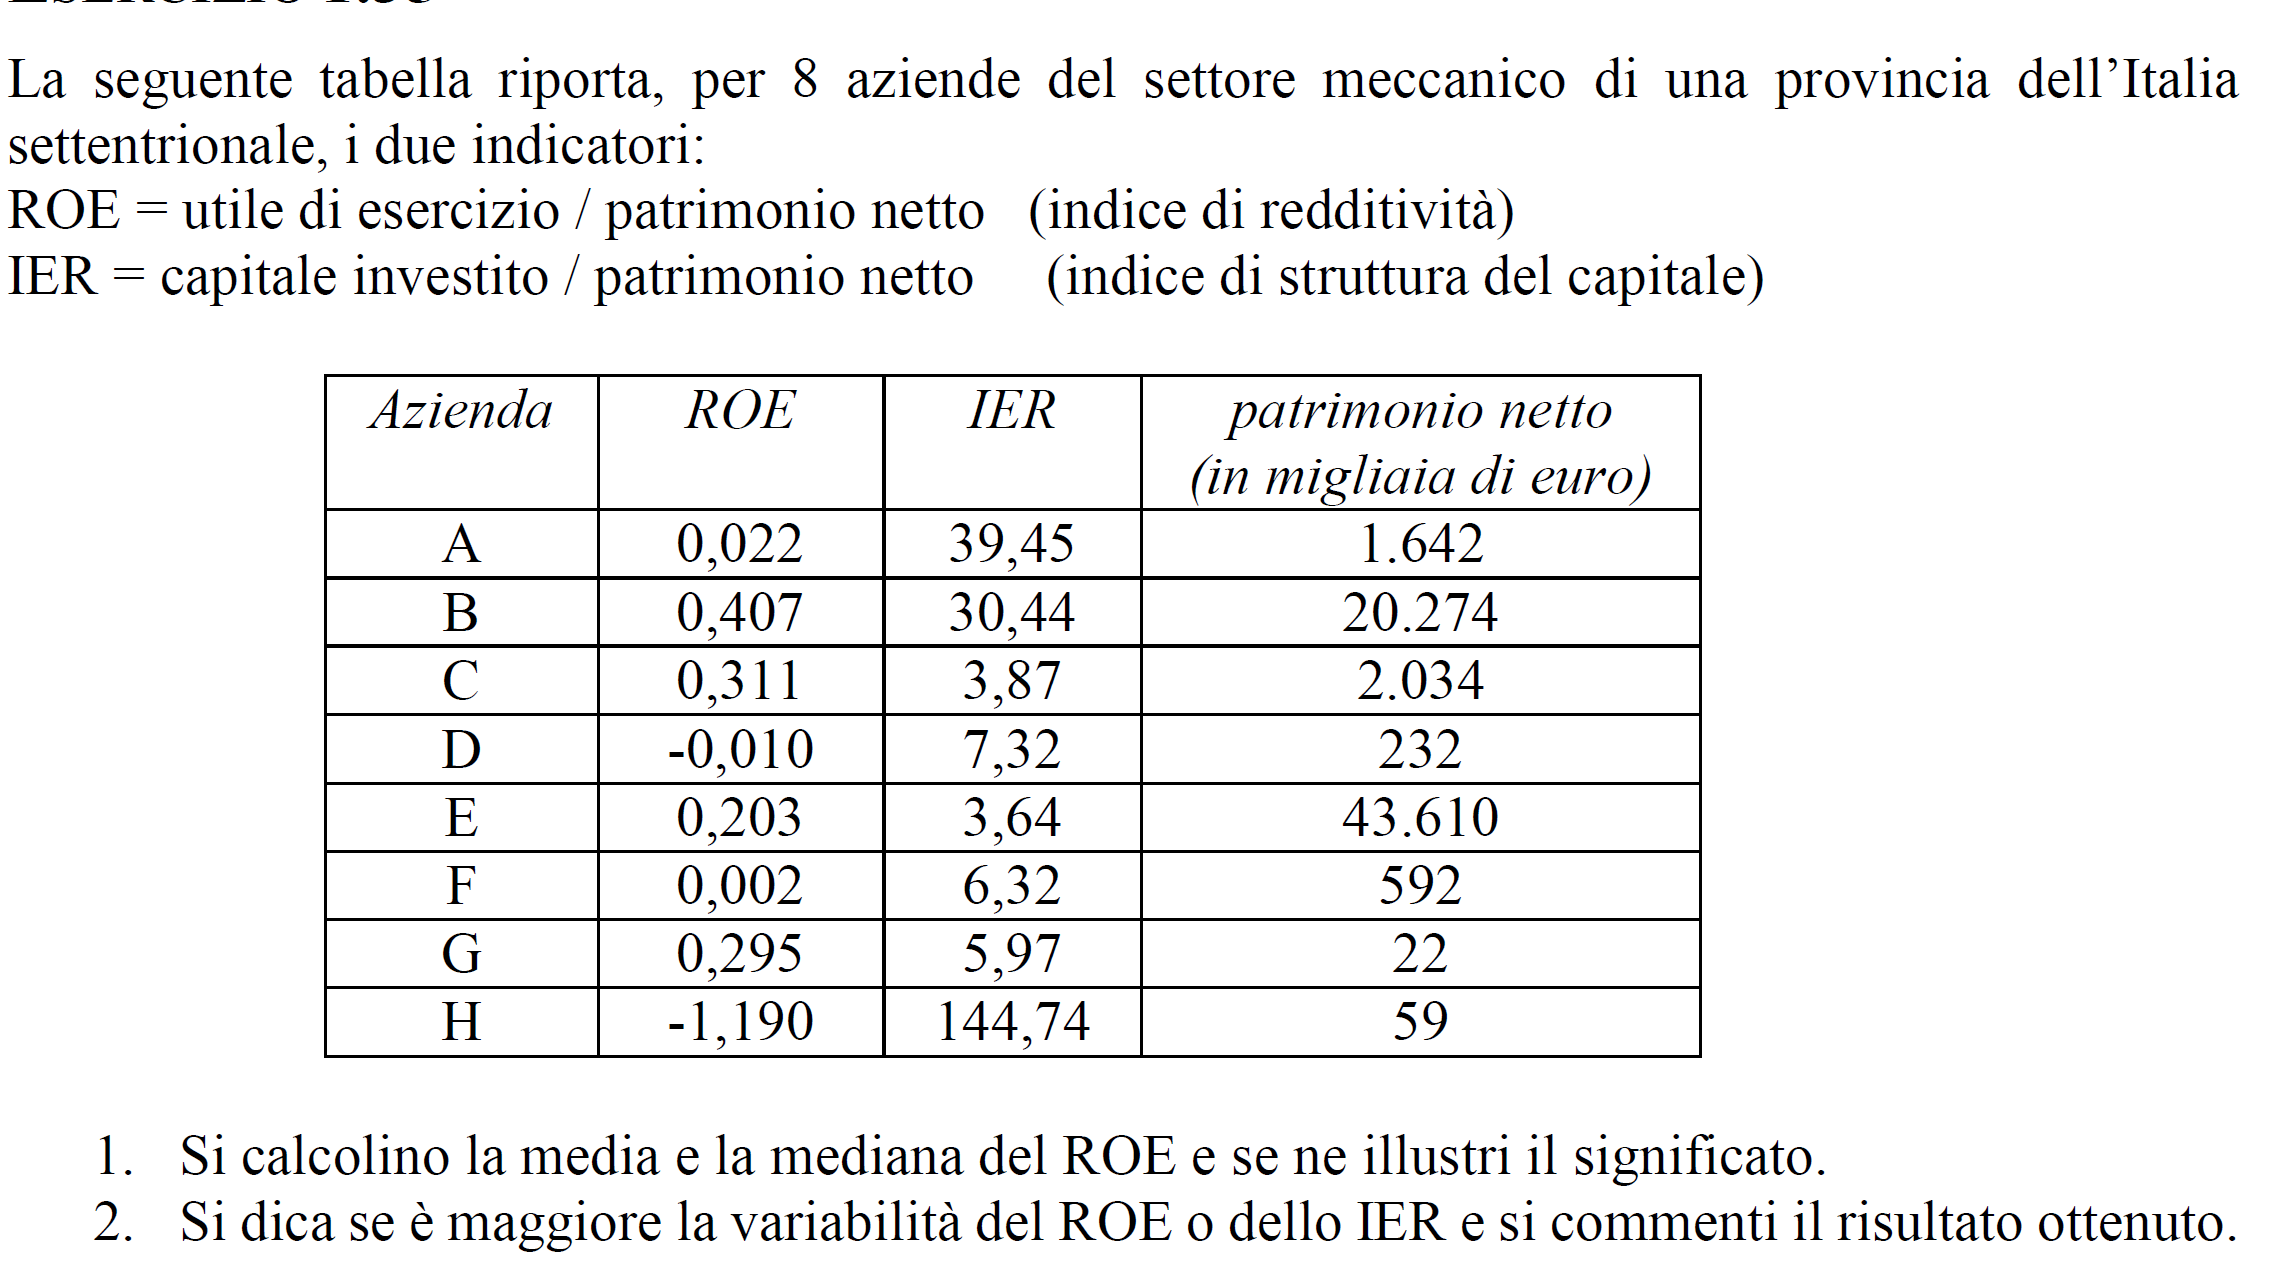

ROE=[0.022;0.407;0.311;-0.010;0.203;0.002;0.295;-1.190];
IER=[39.45;30.44;3.87;7.32;3.64;6.32;5.97;144.74];
PAT=[1642;20274;2034;232;43610;592;22;59];
nomi=cellstr(('A':'H')');
Xt=table(ROE,IER,PAT,'RowNames',nomi);
X=table2array(Xt(:,1:2));
sumw=sum(PAT);
Medie=sum(X.*PAT,1)/sumw;
Sigma=sqrt(sum((X-Medie).^2.*PAT,1)/sumw);
CV=100*Sigma./Medie;
disp('Coefficienti di variazione')

Coefficienti di variazione


disp(Xt.Properties.VariableNames(1:2))

    {'ROE'}    {'IER'}



disp(CV)

   43.2907  106.6098



## 15) Numeri indici

Creare la table di seguito 

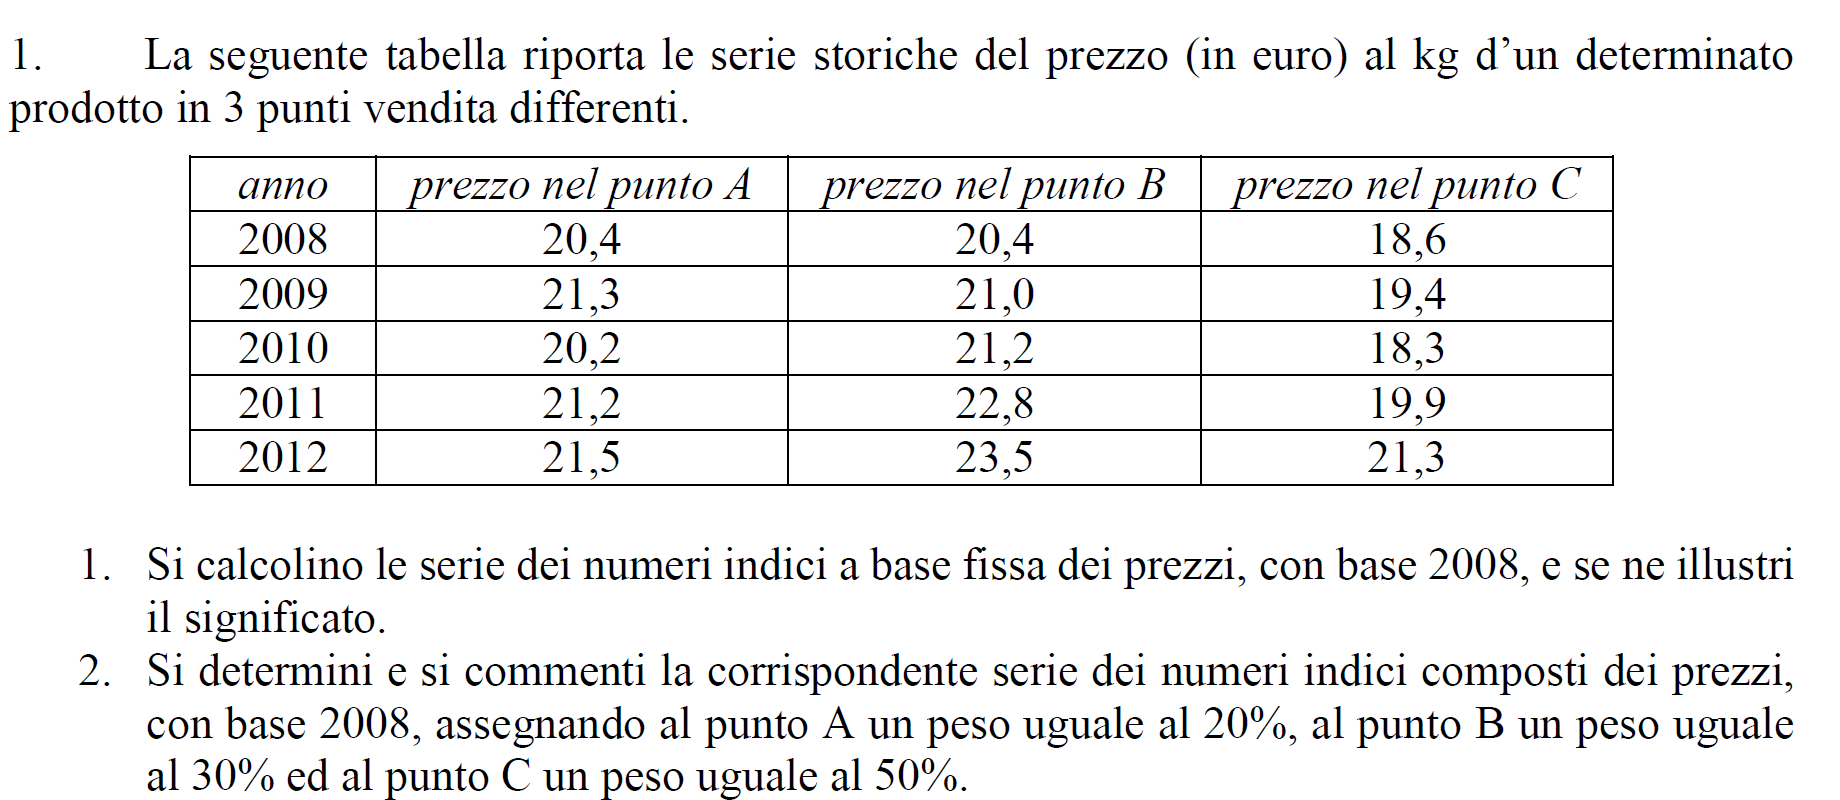

Inserire la serire di NI composti in una table denominata NIcompostit. Mostrare questa table

P=[20.4 20.4 18.6;
    21.3 21 19.4;
    20.2 21.2 18.3;
    21.2 22.8 19.9;
    21.5 23.5 21.3];
base=100*ones(1,size(P,2));
NI=[base; 100*P(2:end,:)./P(1,:)];
pesi=[0.2 0.3 0.5];
NIcomposti=sum(NI.*pesi,2);
NIcompostit=array2table(NIcomposti,'RowNames',string(2008:2012));
disp(NIcompostit)

            NIcomposti
            __________

    2008         100  
    2009      103.92  
    2010      100.17  
    2011      107.81  
    2012       112.9  



## 16) Calcolare moda e mediana dei seguenti giudizi (C>B>A)

B A B A A B C B A B A C B C C B A C

aa=["B" "A" "B" "A" "A" "B" "C" "B" "A" "B" "A" "C" "B" "C" "C" "B" "A" "C"];
% aa viene definito come vettore categorico ordinale
aa=categorical(aa,'Ordinal',true)

aa = 1×18 categorical array
     B      A      B      A      A      B      C      B      A      B      A      C      B      C      C      B      A      C 


mode(aa)

ans = categorical
     B 


median(aa)

ans = categorical
     B 


## 17) Scostamenti standardizzati

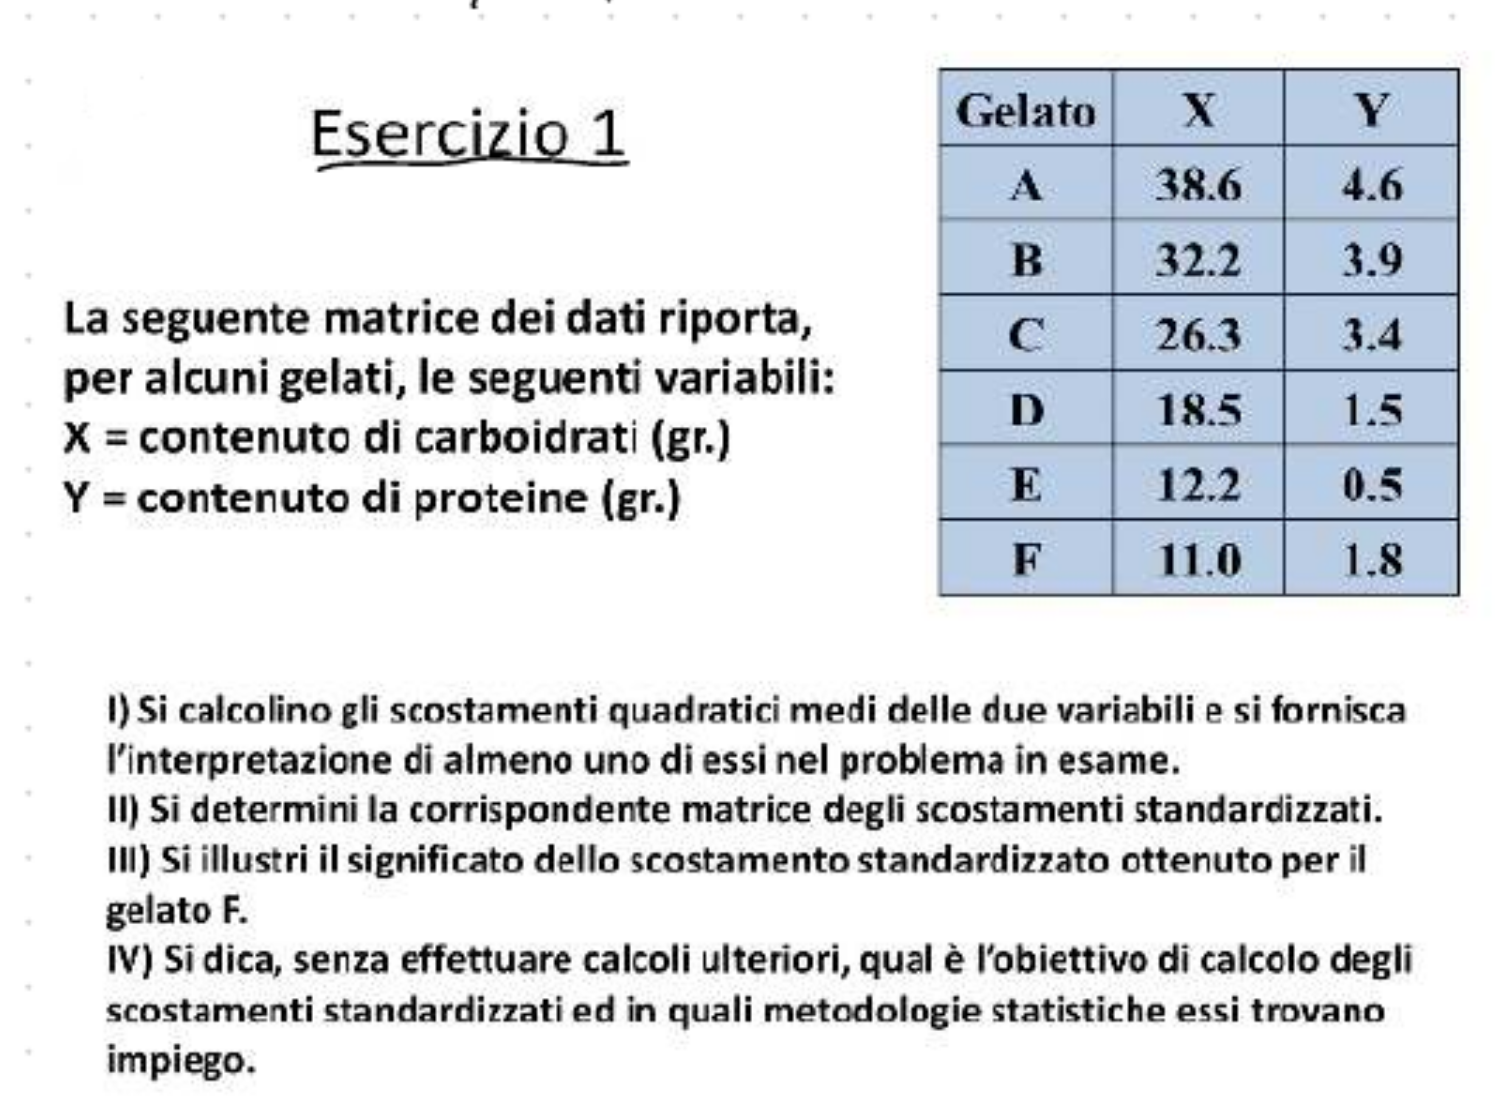

            **V) Calcolare la matrice degli scostamenti standardizzati robusti.**

X=[38.6 4.6; 32.2 3.9; 26.3 3.4; 18.5 1.5; 12.2 0.5; 11 1.8];
% Z = matrice scostamenti standardizzati
Z=zscore(X);
% Zrob matrice degli scostamenti standardizzati robusti
Zrob=zscoreFS(X);


## 18) Generare una matrice ortogonale di dimensione 6x6.

## Verificare l'ortogonalità della matrice e calcolare il determinante.

k=6;
X=gallery("orthog",k)

X =     0.2319    0.4179    0.5211    0.5211    0.4179    0.2319
    0.4179    0.5211    0.2319   -0.2319   -0.5211   -0.4179
    0.5211    0.2319   -0.4179   -0.4179    0.2319    0.5211
    0.5211   -0.2319   -0.4179    0.4179    0.2319   -0.5211
    0.4179   -0.5211    0.2319    0.2319   -0.5211    0.4179
    0.2319   -0.4179    0.5211   -0.5211    0.4179   -0.2319



% Verifico che l'inversa sia uguale alla trasposta
assert(max(abs(X'*X-eye(k)),[],"all")<1e-13,"Matrice non ortogonale")
% Il determinante della matrice ortogonale è 1 o -1
disp(["Determinante=" num2str(det(X))])

    "Determinante="    "-1"

